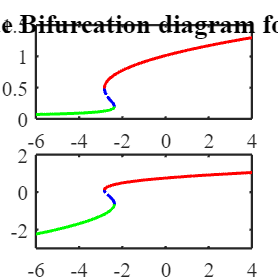

load('COBASaddleResults.mat')

% Set default properties for the current script
set(0, 'DefaultAxesFontName', 'Times New Roman');
set(0, 'DefaultTextFontName', 'Times New Roman');

COBAg = cat(2, flip(COBAg(1:300)), flip(COBAg(301:end)));
COBASaddleR = cat(2, flip(COBASaddleR(1:300)), flip(COBASaddleR(301:end)));
COBASaddleV = cat(2, flip(COBASaddleV(1:300)), flip(COBASaddleV(301:end)));

COBAg1 = COBAg(1:310);
COBAg2 = COBAg(310:322);
COBAg3 = COBAg(322:end);
COBASaddleR1 = COBASaddleR(1:310);
COBASaddleR2 = COBASaddleR(310:322);
COBASaddleR3 = COBASaddleR(322:end);
COBASaddleV1 = COBASaddleV(1:310);
COBASaddleV2 = COBASaddleV(310:322);
COBASaddleV3 = COBASaddleV(322:end);

figure('Units', 'inches', 'Position', [0, 0, 6, 10]); % 7 pulgadas de ancho, 7 pulgadas de alto
sgtitle('COBA Saddle-Node Bifurcation diagram for g = 1.8 and E = 6', 'FontSize', 18, 'FontWeight', 'bold'); % Título general del subplot

% Primer subplot
subplot(2, 1, 1);
plot(COBAg1, COBASaddleR1, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(COBAg2, COBASaddleR2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
plot(COBAg3, COBASaddleR3, '-r', 'LineWidth', 2); % Línea roja sólida para y3
hold off;
set(gca, 'FontSize', 14);
ylabel('r^*', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlim([-4 3]);
ylim([0 1.5]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes

% Segundo subplot
subplot(2, 1, 2);
plot(COBAg1, COBASaddleV1, '-g', 'LineWidth', 2); % Línea verde sólida para y1
hold on;
plot(COBAg2, COBASaddleV2, '-.b', 'LineWidth', 2); % Línea azul con puntos para y2
plot(COBAg3, COBASaddleV3, '-r', 'LineWidth', 2); % Línea roja sólida para y3
hold off;
set(gca, 'FontSize', 14);
ylabel('v^*', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold');
xlabel('$\bar{\eta}$', 'FontSize', 15, 'FontAngle', 'italic', 'FontWeight', 'bold', 'Interpreter', 'latex');
xlim([-4 3]);
ylim([-3 2]);
set(gca, 'LineWidth', 1.5); % Establece el ancho de línea de los ejes


% Mejora la presentación de la figura
set(gcf, 'Color', 'w'); % Establece el color de fondo de la figura a blanco

% Alternativamente, puedes usar:
% exportgraphics(gcf, 'COBASaddleNodeBifurcation.png', 'Resolution', 300); % Guarda con mayor resolución
